# Dynamic Structural Econometrics - Unobserved heterogeneity and CCP estimation

Prepared by [Aaron Barkley, University of Melbourne](https://sites.google.com/site/aaronmbarkley)

## The Expectation-Maximization (EM) Algorithm

We start with an overview of the Expectation-Maximization algorithm. Formally described by Dempster et al (1977), the EM algorithm provides a computationally convenient way to obtain maximum likelihood estimates for "incomplete data" environments. For our purposes, we can think of settings in which each observation in the data is generated by one of two different distribution types. However, the econometrician does not observe which data point has been generated by each type, and only observes the overall distribution. The goal is to identify the distribution of each type and the distribution of the latent variable that governs the distribution over types.

As an example, suppose we have the following data:

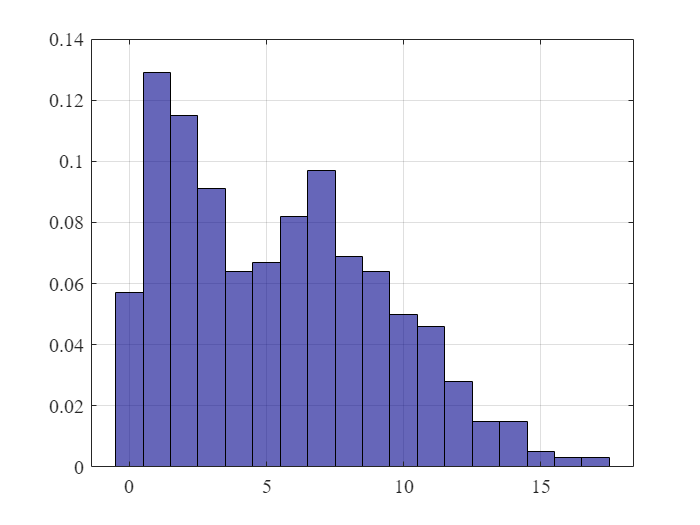

rng(2023);
nobs=1000;
p=rand([nobs,1]);
Y=(p>0.6).*poissrnd(2,[nobs,1]) + (p<=0.6).*poissrnd(8,[nobs,1]);
histogram(Y,'Normalization',"probability")

The above figure shows the empirical distribution of 1000 observations of an integer-valued random variable $Y$. Suppose we would like to fit a parametric model to this data. The main feature of the data that complicates this exercise is that the data is bimodal with a heavy right tail, and few (if any) standard distributions for discrete random variables will accurately capture this feature. To test, this, let's try fitting two common parametric distributions, Poisson and Negative Binomial, and see how they do.

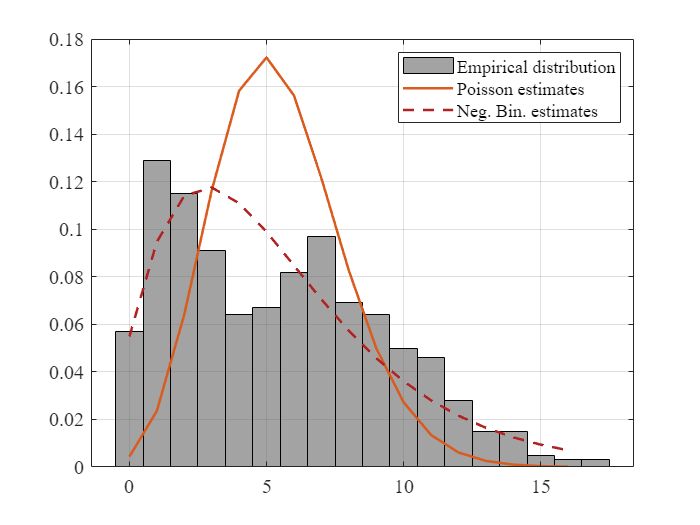

poiss_hat = poissfit(Y);
nbin_hat = nbinfit(Y);
x=0:16;
histogram(Y,'Normalization','pdf','FaceColor',[0.4,0.4,0.4]);
hold on
plot(x,poisspdf(x,poiss_hat));
plot(x,nbinpdf(x,nbin_hat(1),nbin_hat(2)),'--');
hold off;
legend('Empirical distribution','Poisson estimates','Neg. Bin. estimates','location','northeast')

As we can see from the figure above, the results are not encouraging. Simple parametric models may not suffice to accurately capture the qualitative features of the empirical distribution. While we could consider nonparametric approaches to estimating the distribution, this will have demanding data requirements. We also might have other reasons to believe that the distribution is generated by a finite number of different "types" of random draws that are mixed together in the overall distribution of $Y$. 

A common way to estimate these distributions is to consider a mixture model. That is, we will assume that each draw of $Y$ is obtained from distribution $F_1$ with probability $\pi_1$ and distribution $F_2$ with probability $\pi_2$. The mixing parameters $p_1, p_2$ govern the distribution over types, while the distributions $F_1, F_2$ describe the distribution of outcomes within each type. Typically, we will parameterize the distributions $F_1$ and $F_2$ with parameters $\theta_1, \theta_2$. Noting the restriction that $p_1 + p_2 = 1$, we have three parameters we need to estimate: $\theta_1$, $\theta_2$, and $\pi \equiv \pi
_1$. 

The log-likelihood for observation $y_i$ can be expressed as 


$$\ell_i = \log \big( \pi f_1(y_i; \theta_1) + (1-\pi) f_2(y_i;\theta_2) \big)$$


Practical applications have found that direct maximum likelihood approaches to estimating these parameters perform poorly -- convergence may be slow, there can be many local optima, and the estimates may be extremely sensitive to starting values for the parameters. The alternative approach of Dempster et al (1977) is to update the parameters $\pi$ and $(\theta_1, \theta_2)$ in separate stages. The main features of the estimator can be described in four steps:

- Fix initial values for $\theta_1^{(0)}, \theta_2^{(0)}$, and $\pi^{(0)}$ and set convergence criteria.

- Given the current values for $\theta_1^{(0)}, \theta_2^{(0)}$, compute the probability of each observation type, i.e., calculate Pr$(Z_{ij}=1 | \theta_1^{(0)}, \theta_2^{(0)})$for $j = 1,2$. This yields an updated value for $\pi$ and pointwise estimates for the probability that each observation $i$ is of type $j$.

- Hold fixed the type probabilities for each $Z_{ij}$ computed in step 2 and maximize the likelihood with respect to $\theta_1, \theta_2$ given these probabilities. This yields updated values for $\theta_1, \theta_2$.

- Repeat steps 2-3 until convergence (per-iteration change in the overall likelihood is "small").

We will implement this algorithm on the data set above using the assumptions that (i) there are two components in the mixture (i.e., observations are each associated with one of two unobserved types) and (ii) the two types $j \in \{1,2\}$ each follow a Poisson distribution with parameter $\theta_j$.

% Step 1 (a): initial values for theta and lambda
obs=size(Y,1);
theta_0=[1,2];
pi_0=[0.5,0.5];

% Step 1 (b): specify convergence criteria
iter=1;
maxiter=1000;
lik0=10000;
normdiff=10000;
tolerance=1e-6;
while normdiff>tolerance && iter<=maxiter


### Expectation step. 

The expectation step takes the current values of $\theta_1, \theta_2$ as fixed and calculates the probability of observation $y_i$ being of type 1 ($Z_{i1}=1$) or type 2 ($Z_{i2}=1$). We can write the density function of $Y$ conditional on $\theta$, $\pi
$, and the (unobserved) $Z_{ij}$ as


$$\prod_{k=1}^2 f(Y_i | \theta_k)^{Z_{ik}}$$


Similarly, the distribution of $Z_{i}$ conditional on $\theta$ and $\pi
$ is 


$$\prod_{k=1}^2 \pi_k^{Z_{ik}}$$


where $\lambda_1 + \lambda_2 =1$. These equations together with Bayes theorem imply that the conditional distribution of the $Z_{ij}$ are the proportional likelihood of each mixture component $j$ weighted by the current estimates of the mixture weights $\lambda$:


$$E[Z_{ij} | Y, {\theta}^{(m)}, \pi^{(m)}] = \frac{\pi^{(m)}_j f(Y_i | \theta^{(m)}_j)}{\pi^{(m)}_1 f(Y_i | \theta^{(m)}_1) + \pi^{(m)}_2 f(Y_i | \theta^{(m)}_2)}$$


    % Expectation:
    EZ=zeros(obs,length(pi_0));
    temp_pdf=poisspdf(repmat(Y,1,length(theta_0)),repmat(theta_0,obs,1));
    for j=1:length(pi_0)
        EZ(:,j)=(pi_0(j)*temp_pdf(:,j))./(temp_pdf*pi_0');
    end


In the code above, the "temp_pdf" variable creates an $N \times 2$ matrix of likelihood values, where the first column is the set of likelihoods associated with $Z_{i1}=1$ and the second column is the set of likelihoods associated with $Z_{i2}=1$:


$$\left[ \begin{array}{c c} f(Y_1 | \theta^{(m)}_1) & f(Y_1 | \theta^{(m)}_2 \\ f(Y_2 | \theta^{(m)}_1) & f(Y_2 | \theta^{(m)}_2 \\ \vdots & \vdots  \\ f(Y_N | \theta^{(m)}_1) & f(Y_N | \theta^{(m)}_2 \end{array} \right]$$


### Maximization step.

The maximization step performs a standard maximum likelihood procedure in which the probabilities of being in each group $E[Z_{ij}]$ are treated as known and fixed. 


$$\mathcal{L} = \sum_{i=1}^N \sum_{k=1}^2 E[Z_{ik} | Y, \theta^{(m)}, \pi^{(m)}] \log(f(Y_i | \theta^{(m)}_j) + \sum_{i=1}^N \sum_{k=1}^2 E[Z_{ik} | Y, \theta^{(m)}, \pi^{(m)}] \log(\pi_j)$$


Because the likelihood is additively separable in $\theta$ and $\lambda$, the maximization step can be done in two parts. Updating $\pi
$ is simple: maximizing $\sum_{i=1}^N \sum_{k=1}^2 E[Z_{ik} | Y, \theta^{(m)}, \pi^{(m)}] \log(\pi_j)$ with respect to $\pi$ simply requires taking the average of the probability of being each type:


$$\pi_j^{(m+1)} = \frac{1}{N} \sum_{i=1}^N E[Z_{ik} | Y, \theta^{(m)}, \lambda^{(m)}]$$


That is, we simply take the mean of each column of the $N \times 2$ "EZ" matrix we computed above. 

Updating $\theta$ requires us to numerically optimize the first component of the log-likelihood function above. 


$$\theta^{(m+1)} = \arg \max_{\theta} \sum_{i=1}^N \sum_{k=1}^2 E[Z_{ik} | Y, \theta^{(m)}, \pi^{(m)}] \log(f(Y_i | \theta_j)$$


Since Matlab has a built-in function for the pmf of a Poisson distribution, this likelihood function can be defined and optimized with two lines of code.

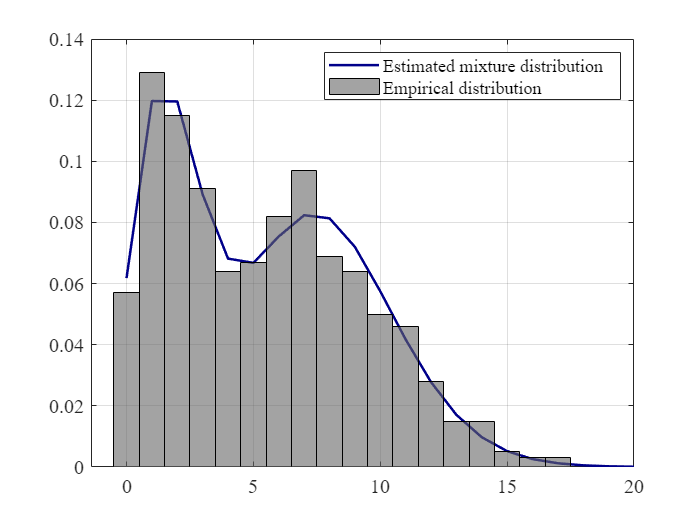

     % Maximization
     theta_fun= @(theta) (-1)*sum(sum(log(poisspdf(repmat(Y,1,length(theta_0)),repmat(theta,obs,1))).*EZ));
     [theta_1,~]=fminsearch(theta_fun,theta_0);
     
     pi_1=(1/obs)*sum(EZ);

The last step in each iteration is to calculate the overall likelihood $\mathcal{L}^{(m+1)} = \sum_{i=1}^N \sum_{k=1}^2 E[Z_{ik} | Y, \theta^{(m)}, \pi^{(m)}] \log(f(Y_i | \theta^{(m+1)}_j) + \sum_{i=1}^N \sum_{k=1}^2 E[Z_{ik} | Y, \theta^{(m)}, \pi^{(m)}] \log(\pi_j^{(m+1)})$ and check for convergence. If $(\mathcal{L}^{(m+1)} - \mathcal{L}^{(m)})^2$ is less than the convergence criteria, we stop. Otherwise, we proceed to the next iteration.

     % Update likelihood:

FiniteMixtureEstimatesTable = 4×2 table
               Estimates    True values
               _________    ___________

    Theta_1      1.9176           2    
    Theta_2      7.9876           8    
    Pi_1        0.41922         0.4    
    Pi_2        0.58078         0.6    


     lik1=sum(sum(log(poisspdf(repmat(Y,1,length(theta_1)),repmat(theta_1,obs,1))).*EZ)) + sum(sum(log(pi_1).*EZ));
     normdiff=(lik0-lik1)^2;

     % Update for next iteration
     lik0=lik1;
     theta_0=theta_1;
     pi_0=pi_1;
     iter=iter+1;
end

ThetaHat=theta_1;
PiHat=pi_1;


With the estimates obtained, let's see how we did:

x=0:20;
Y_fit=PiHat(1)*poisspdf(x,ThetaHat(1))+PiHat(2)*poisspdf(x,ThetaHat(2));
plot(x,Y_fit)
hold on
histogram(Y,'Normalization','probability','FaceColor',[0.4,0.4,0.4]);
hold off
legend('Estimated mixture distribution','Empirical distribution','location','northeast')

This looks much better: the estimated distribution matches the shape of the empirical distribution much more closely. Since we know the true parameters used to generate the data, we can also compare these with the estimated parameters:

FiniteMixtureEstimatesTable = table([ThetaHat'; PiHat'],[2; 8; 0.4; 0.6],'VariableNames',{'Estimates','True values'},'RowNames',{'Theta_1','Theta_2','Pi_1','Pi_2'})

The estimator also converges quickly, taking fewer than 30 iterations to converge.

## Using the EM algorithm in a dynamic discrete choice model

Now we apply the EM algorithm to a dynamic discrete choice model. The basic features of the algorithm do not change: at each iteration, we compute the probability of each individual (or bus) of being of type $s$ given the most recent estimates for $\theta$, and then use these probabilities to obtain a new estimate for $\theta$. 

### Model description and setup

We continue to use the model of Harold Zurcher's bus engine replacement problem introduced in Rust (1987) as the framework for estimation. To briefly reiterate the model, we have the following setup, noting that we now assume that the bus type $s$ is *unobservable:*

- Time is discrete, with $t=1,2,...,\overline{T}$ denoting each period, with $\overline{T} = \infty$.

- Each period, Harold Zurcher chooses between two actions. He can either replace the bus engine, $d_{1t}=1$, or not replace $d_{2t}=1$. These are mutually exclusive, so that $d_{1t} + d_{2t} = 1$.

- Zurcher's payoff depends on a single state variable $x_t$ that represents the mileage of the bus. Mileage advances by a random amount if the bus engine is not replaced and is set to zero if the bus engine is replaced. Denote by $f_d(x_{t+1} | x_t)$ the distribution over next period mileage conditional on current mileage after making choice $d$. When the bus engine is replaced, mileage resets to zero, so that $f_1(x_1 | x_t)=1$ for all $x_t$. Mileage accumulation when the engine is not replaced follows a discrete analog of the exponential distribution up to some maximum mileage $\overline{x}$ where mileage increment is $\Delta_x$.


$$f_2(x_{t+1} | x_t) = \begin{cases} \exp\big(-(x_{t+1} - x_t)\big) - \exp\big(-(x_{t+1} + \Delta_x - x_t)\big) & \mbox{ for } \ d_{t}=2 \ \mbox{ and } \ x_t \leq x_{t+1} \leq \overline{x}, \\ \exp\big(-(\overline{x} - x_t)\big) & \mbox{ for } \ x_{t+1}>=\overline{x},  \\ 0 & \mbox {otherwise.} \end{cases}$$


- In addition to mileage $x_t$, there is a permanent and **unobservable** bus-specific type $s \in \{1,..,S\}$. Assume that the deterministic component of flow payoffs for each action $j=1,2$ for a bus of type $s$ are given by


$$u_{1t}  =  0$$



$$u_{2t}  =   \theta_1 + \theta_2 x_t + \theta_3 s$$


- Payoffs also have an additively separable idiosyncratic component $\epsilon_{jt}$ so that the total flow payoff from choice $j$ in period $t$ is $u_{jt}(x_t) + \epsilon_{jt}$. We assume that $\epsilon_{jt}$ are i.i.d draws from a  Type I EV distribution.

- Denoting the optimal decision rule at $t$ by $d^o_t(x_t, s,\epsilon_t) = [d^o_{1t}(x_t,s,\epsilon_{1t}), \ d^o_{2t}(x_t,s,\epsilon_{2t})]$, we define the ex-ante value function for state $x_t$ in period $t$ as


$$V_t(x_t,s) \equiv E \Big\{\sum_{\tau=t}^{\overline{T}} \sum_{j=1}^2 \beta^{\tau - t - 1} d^o_{jt}(x_{\tau},s, \epsilon_{\tau}) (u_{j\tau}(x_{\tau},s) + \epsilon_{j\tau})  \Big\}$$


- The conditional value function $v_{jt}(x_t)$ is the value function for choice $j$ in period $t$ and state $x_t$ less the utility shock $\epsilon_{jt}$. In the case of Zurcher's bus engine replacement problem, these functions can be expressed as 


$$v_{1}(x_t,s) = \beta \sum_{x=1}^{\overline{x}} V(x,s) f_1(x \ | x_{t+1})$$



$$v_{2}(x_t,s) = \theta_1 + \theta_2x_t + \theta_3 s + \beta \sum_{x=1}^{\overline{x}} V(x,s) f_1(x \ | x_{t+1})$$


- Note that all $t$ subscripts have been removed from value functions and state transitions: this is a stationary, infinite horizon problem.

- In the binary choice setting with Type I EV preference shocks we can express conditional choice probabilities very simply:


$$p_2(x_t,s) = \mbox{Pr}(v_2(x_t,s) + \epsilon_{2t} \geq v_1(x_t,s) + \epsilon_{1t}) \ = \ \mbox{Pr}\big(\epsilon_{1t} - \epsilon_{2t} \leq v_2(x_t,s) - v_1(x_t,s)\big) \ = \ \frac{\exp\Big(v_2(x_t,s) - v_1(x_t,s)\Big)}{ 1 + \exp\Big(v_2(x_t,s) - v_1(x_t,s))\Big)}$$


- Representation: finally, we can use the results of Hotz and Miller (1993) to express the difference between the value function $V_t(x_t,s)$ and conditional value function $v_{j}(x_t,s)$:


$$V(x_t,s) - v_{j}(x_t,s) = \psi_j(p(x_t,s)), \quad$$
 

where $\quad \psi_j(p(x_t,s)) = \gamma - \log(p_j(x_t,s))$ when $\epsilon_{ijt} \sim$ Type I EV, where $\gamma \approx 0.577$ is the Euler-Mascheroni constant. 

clear
rng(57);
% States (mileage)
x_min = 0.0 ; x_max = 10.0; 
delta_x = 0.5; 
x_len = (x_max-x_min)/delta_x+1;
x = linspace(x_min, x_max, x_len);
% State transitions
x_tday = repmat(x, [x_len,1]);
x_next = x_tday';                                      
f = (x_next >= x_tday)' .* exp(- (x_next - x_tday)') .* (1 - exp(-delta_x)); 
f(:,end) = 1 - sum(f(:,1:(end-1)), 2); % The last column is set so that the sum of probs is 1
F = cumsum(f(:,:), 2);

F2=f;
F1=zeros(size(f));
F1(:,1)=1;
emc = double(eulergamma);

% Define parameters and simulate data
beta = 0.9;
theta = [2.00, -0.15, 1.0];
T=40;
S=1:2;
X=x;
N=1000;
pi=0.4; 
[data_t, data_x, data_s, data_d, data_x_index] = generate_data(N, T, S, f, F, X,beta, pi, theta);

% Optional: save data
% Data_vars={'data_t', 'data_x', 'data_s', 'data_d', 'data_x_index'};
% Const_vars={'beta','theta','S','X','x_len','pi','T','x','N','f','F','F1','F2','emc'};
% All_vars=[Data_vars, Const_vars];
% save("Bus_engine_unobs_het_data.mat",All_vars{:});

### Estimation

We begin by setting initial values for the parameters $\theta, \pi,$ and $q_{ns}$, and use the initial values for $q_{ns}$ to initialize the conditional choice probabilities $p_1^{(0)}(x,s)$.

The convergence parameter is a tolerance level of 1e-7, and we check for convergence by testing the percentage change in the likelihood for values 25 iterations apart. Finally, we set the maximum number of iterations to 1000 and include a check (and error message) in case we reach this level before converging.

% Optional: load data
% load("Bus_engine_unobs_het_data.mat");
iter=1;
max_iter=1000;
tol=1e-6;
exit_flag=0;
stored_lik_vals=zeros(max_iter,1);

theta_0=0.1*ones(3,1);
pi_hat=0.5;
q_new=[pi_hat*ones(N,1), (1-pi_hat)*ones(N,1)];
ccp_hat = zeros(length(X),length(S));
epsilon=1e-4;
for j=1:length(X)
    for s=1:length(S)
        ccp_hat(j,s) = sum(repmat(q_new(:,s),[T,1]).*(data_x_index(:)==j).*(data_d(:)==1))/sum(repmat(q_new(:,s),[T,1]).*(data_x_index(:)==j));
    end
end
ccp_hat=max(epsilon, min(1-epsilon,ccp_hat));


To illustrate the method as it applies to the bus engine replacement case, we go through one iteration first before putting each term inside the loop that completes the estimation.

#### Expectation step.

With initial values for the parameters established, we first need to calculate the likelihood for each observation bus $n$, time period $t$, and bus type $s$. Recall that in the finite Poisson mixture in the example above, we updated the guesses for the probability that observation $i$ was type $j$ by using the $\pi$-weighted likelihoods of observing outcome $Y_i$ conditional on being type $j$ and having type-specific parameters $\theta_j$. With the dynamic bus engine replacement problem, we proceed similarly. However, we have to remember that the relevant likelihood for establishing whether bus $n$ is of type $s$ is the *sequence* of replacement decisions $\{d_{nt}\}_{t=1}^T$ made for that bus. Therefore, we calculate the individual likelihood components $\ell_{nt}$ for each period, bus, and type, and then we take the product across time periods $t$ to compute the overall likelihood associated with each bus type $s$.

Each individual likelihood term can be calculated as 


$$\ell_{nt}(d_{nt} | x_{nt}, s, p_1, \theta) = \frac{d_{1nt} + d_{2nt} \exp(v_2(x_{nt},s) - v_1(x_{nt},s))}{1+\exp(v_2(x_{nt},s) - v_1(x_{nt},s))}$$


where we exploit the one-period finite dependence property inherent to the renewal of the bus engine to express the differences conditional value functions in terms of the one-period ahead conditional choice probabilities:


$$v_2(x_{nt},s) - v_1(x_{nt},s) = \theta_0 + \theta_1x_{nt} + \theta_2 s + \beta [ \log(p_1(0, s)) - \sum_{x' \in \mathcal{X}}\log(p_1(x',s)) f_2(x' | x_{nt})]$$


u2 = theta_0(1) + theta_0(2)*X' + theta_0(3)*S;
v1_ccp = repmat(beta*(-log(ccp_hat(1,:))) + beta*emc,[length(X),1]);
v2_ccp = u2 + beta*F2(:,:)*(0 - log(ccp_hat(:,:))) + beta*emc;

% Expectation step:
likelihood_pointwise_1=((data_d(:)==2).*exp((v2_ccp(data_x_index(:),1)-v1_ccp(data_x_index(:),1)))+(1-(data_d(:)==2)))./(1+exp(v2_ccp(data_x_index(:),1)-v1_ccp(data_x_index(:),1)));
likelihood_pointwise_2=((data_d(:)==2).*exp((v2_ccp(data_x_index(:),2)-v1_ccp(data_x_index(:),2)))+(1-(data_d(:)==2)))./(1+exp(v2_ccp(data_x_index(:),2)-v1_ccp(data_x_index(:),2)));


The likelihood associated with each bus $n$ conditional on engine type $s$ is the product of the likelihood of the sequence of decisions $\{d_{nt}\}_{t=1}^T$ conditional on the states $x_{nt}$, engine type $s$, conditional choice probabilities $p_1$, and utility parameters $\theta$: $\prod_{t=1}^T \ell_{nt}(d_{nt} | x_{nt}, s, p_1, \theta)$. This is the term that captures the observation-level likelihood terms $f(Y_i | \theta)$from our simple EM algorithm example above. As before, we weight the engine-type specific likelihoods by the mixing parameter $\pi_s$ yielding an overal per-bus estimate of the probability of being engine type $s$ of


$$q^{(m+1)}_{ns} = \frac{\pi^{(m)}_s \prod_{t=1}^T \ell_{nt}(d_{nt} | x_{nt}, s, p_1^{(m)}, \theta^{(m)})}{\sum_{s'=1}^S \pi^{(m)}_{s'} \prod_{t=1}^T \ell_{nt}(d_{nt} | x_{nt}, s', p_1^{(m)}, \theta^{(m)})}$$


ll_pw1=reshape(likelihood_pointwise_1,[N,T]);
ll_pw2=reshape(likelihood_pointwise_2,[N,T]);
likelihood_by_n=[prod(ll_pw1,2), prod(ll_pw2,2)];

q_new(:,1) = pi_hat*likelihood_by_n(:,1)./(pi_hat*likelihood_by_n(:,1) + (1-pi_hat)*likelihood_by_n(:,2));
q_new(:,2) = 1-q_new(:,1);


#### Maximization step.

Having established the expectation that each bus $n$ is of type $s$ in the previous step, we now perform that maximization step of the algorithm. As before, updating the mixing parameter $\pi$ is simple, as we simply take the mean of the bus-level probabilities of being of type $s$:


$$\pi^{(m+1)}_s = \frac{1}{N} \sum_{n=1}^N q^{(m+1)}_{ns}$$


To update the utility parameters $\theta$, we first need to update the conditional choice probabilities $p_1(x,s)$since we are using CCP methods to calculate the likelihood terms. We update the conditional choice probabilities using the bin estimator after applying weights via the per-bus probability of being in state $s$:


$$p^{(m+1)}_1(x,s) = \frac{\sum_{n=1}^N \sum_{t=1}^T d_{1nt} q^{(m+1)}_{ns} 1\{x_{nt}=x\}}{\sum_{n=1}^N \sum_{t=1}^T q^{(m+1)}_{ns} 1\{x_{nt}=x\}}$$


The last maximization step is to update the utility parameters $\theta$. Here we maximize the likelihood, again weighting each likelihood component $\ell_{nt}(d_{nt} | x_{nt}, s_n, p_1^{(m+1)}, \theta)$ by the probability that bus $n$ is of type $s$ using the estimates for $q_{ns}$ obtained in the previous step:


$$\theta^{(m+1)} = \arg \max_{\theta} \sum_{n=1}^N \sum_{s=1}^S \sum_{t=1}^T q_{ns}^{(m+1)} \log\big(\ell_{nt}(d_{nt} | x_{nt}, s_n, p_1^{(m+1)}, \theta) \big)$$


% Maximization step:
pi_hat = mean(q_new(:,1));
ccp_new = zeros(length(X),length(S));
epsilon=1e-4;
for j=1:length(X)
    for s=1:length(S)
        ccp_new(j,s) = sum(repmat(q_new(:,s),[T,1]).*(data_x_index(:)==j).*(data_d(:)==1))/sum(repmat(q_new(:,s),[T,1]).*(data_x_index(:)==j));
    end
end
never_reached=isnan(ccp_new(:)); % keep track of states that never occur in the data
ccp_new=max(epsilon, min(1-epsilon,ccp_new)); % Makes sure that all probabilities are in the open interval (0,1), as "1" and "0" observations cause problems.
lik_fun = @(theta) ccp_likelihood_inner(theta,X,S,f,data_x_index,q_new,data_d,ccp_new,beta,T);

[updated_theta,fval] = fminunc(lik_fun,theta_0,optimoptions('fminunc','Display','none'));


Finally, we include everything in a while loop so as to iterate until convergence:


tic;
cond=0;
while cond==0 && iter<max_iter
    
    u2 = theta_0(1) + theta_0(2)*X' + theta_0(3)*S;
    v1_ccp = repmat(beta*(-log(ccp_hat(1,:))) + beta*emc,[length(X),1]);
    v2_ccp = u2 + beta*F2(:,:)*(0 - log(ccp_hat(:,:))) + beta*emc;
    
    % STEP 1: Expectation 
    likelihood_pointwise_1=((data_d(:)==2).*exp((v2_ccp(data_x_index(:),1)-v1_ccp(data_x_index(:),1)))+(1-(data_d(:)==2)))./(1+exp(v2_ccp(data_x_index(:),1)-v1_ccp(data_x_index(:),1)));
    likelihood_pointwise_2=((data_d(:)==2).*exp((v2_ccp(data_x_index(:),2)-v1_ccp(data_x_index(:),2)))+(1-(data_d(:)==2)))./(1+exp(v2_ccp(data_x_index(:),2)-v1_ccp(data_x_index(:),2)));

    ll_pw1=reshape(likelihood_pointwise_1,[N,T]);
    ll_pw2=reshape(likelihood_pointwise_2,[N,T]);
    likelihood_by_n=[prod(ll_pw1,2), prod(ll_pw2,2)];

    q_new(:,1) = pi_hat*likelihood_by_n(:,1)./(pi_hat*likelihood_by_n(:,1) + (1-pi_hat)*likelihood_by_n(:,2));
    q_new(:,2)=1-q_new(:,1);

    
    % STEP 2: Maximization 
    pi_hat = mean(q_new(:,1));
    ccp_new = zeros(length(X),length(S));
    epsilon=1e-4;
    for j=1:length(X)
        for s=1:length(S)
            ccp_new(j,s) = sum(repmat(q_new(:,s),[T,1]).*(data_x_index(:)==j).*(data_d(:)==1))/sum(repmat(q_new(:,s),[T,1]).*(data_x_index(:)==j));
        end
    end
    never_reached=isnan(ccp_new(:)); % keep track of states that never occur in the data
    ccp_new=max(epsilon, min(1-epsilon,ccp_new)); % Makes sure that all probabilities are in the open interval (0,1), as "1" and "0" observations cause problems.
    lik_fun = @(theta) ccp_likelihood_inner(theta,X,S,f,data_x_index,q_new,data_d,ccp_new,beta,T);

    [updated_theta,fval] = fminunc(lik_fun,theta_0,optimoptions('fminunc','Display','none'));

    % STEP 3: Re-calculate pointwise likelihood with updated thetas, pi
    % hat, and ccps, and check convergence 
    u2 = updated_theta(1) + updated_theta(2)*X' + updated_theta(3)*S;
    v1_ccp = repmat(beta*(-log(ccp_new(1,:))) + beta*emc,[length(X),1]);
    v2_ccp = u2 + beta*F2(:,:)*(0 - log(ccp_new(:,:))) + beta*emc;

    likelihood_pointwise_1=((data_d(:)==2).*exp((v2_ccp(data_x_index(:),1)-v1_ccp(data_x_index(:),1)))+(1-(data_d(:)==2)))./(1+exp(v2_ccp(data_x_index(:),1)-v1_ccp(data_x_index(:),1)));
    likelihood_pointwise_2=((data_d(:)==2).*exp((v2_ccp(data_x_index(:),2)-v1_ccp(data_x_index(:),2)))+(1-(data_d(:)==2)))./(1+exp(v2_ccp(data_x_index(:),2)-v1_ccp(data_x_index(:),2)));

    temp_val=sum(q_new(:,1).*log(prod(reshape(likelihood_pointwise_1,[N,T]),2)) + q_new(:,2).*log(prod(reshape(likelihood_pointwise_2,[N,T]),2))) + sum(log(pi_hat)*q_new(:,1) + log(1-pi_hat)*q_new(:,2));
    
    stored_lik_vals(iter)=temp_val;
    if iter>50
        if abs((stored_lik_vals(iter) - stored_lik_vals(iter-25))./stored_lik_vals(iter))<tol
            cond=1;
        end
    end    
    
    % STEP 4: Update values and continue to next iteration if cond==0
    iter=iter+1;
    theta_0=updated_theta;
    ccp_hat=ccp_new;
    if iter >= max_iter
        exit_flag=1;
        disp('Maximum number of iterations reached')
    end
end
toc

Elapsed time is 75.517123 seconds.




UnobservedHetCCP_EstimatesTable = table([updated_theta; pi_hat],[theta'; pi],'VariableNames',{'CCP estimates','True values'},'RowNames',{'Theta_0','Theta_1','Theta_2','Pi'})

UnobservedHetCCP_EstimatesTable = 4×2 table
               CCP estimates    True values
               _____________    ___________

    Theta_0        1.9939              2   
    Theta_1      -0.14786          -0.15   
    Theta_2        1.0279              1   
    Pi            0.41936            0.4   


*Important disclaimer:* in the data generation function, we have assigned *exogenous* state variables in the initial period $t=1$. This is unlikely to hold in general. Suppose all buses had started with zero mileage in period 0 but we, the econometricians, only observed the buses starting in period 10. Because the mileage accumulation and replacement decisions will be correlated with the unobserved type $s$, we will have an initial conditions problem: the first state that we observed the bus, $x_{n1}$, will be correlated with the unobserved type, and we will need to control for this in order to obtain consistent estimates. There are several ways to account for this; see the supplementary material for Arcidiacono and Miller (2011) for one such implementation.

## Functions

function [ccp_lik] = ccp_likelihood_inner(theta,X,S,x_tran,data_x_index,q,data_d,ccp_hat,beta,T)
emc = double(eulergamma);
u2 = theta(1) + theta(2)*X' + theta(3)*S;
v1_ccp = repmat(beta*(-log(ccp_hat(1,:))) + beta*emc,[length(X),1]); 
v2_ccp = u2 + beta*x_tran(:,:)*(0 - log(ccp_hat(:,:))) + beta*emc;
q_use=repmat(q(:,1),[1,T]);
q_use(q_use==2)=0;
ccp_lik_1 = -sum(q_use(:).*((data_d(:)==2).*(v2_ccp(data_x_index,1)-v1_ccp(data_x_index,1)) - log(1+exp(v2_ccp(data_x_index,1)-v1_ccp(data_x_index,1)))));
ccp_lik_2 = -sum((1-q_use(:)).*((data_d(:)==2).*(v2_ccp(data_x_index,2)-v1_ccp(data_x_index,2)) - log(1+exp(v2_ccp(data_x_index,2)-v1_ccp(data_x_index,2)))));
ccp_lik = ccp_lik_1+ccp_lik_2;

end


The value function iteration and data generation functions below are only used in generating the data, not in estimating the model. We have modified the data generating function slightly compared with previous lecture notes to assign exogenous mileage state variables $x$ to each bus in the first time period observed, rather than letting the model run for a certain number of periods before sampling mileage observations. This allows us to ignore the initial conditions problem in estimating the distribution of $s$ (see disclaimer above).

function [value_function,value_diff,ccps] = value_function_iteration(S,x_tran,X, beta,theta)
x_len = length(unique(X));
emc = double(eulergamma);
value_function_2 = zeros(x_len,length(S));
ccps=zeros(x_len,length(S));
value_diff=1;
max_iter=1000;
iter=1;
while value_diff>1e-5 && iter < max_iter
    value_function_1 = value_function_2;
    for s=1:length(S)
                v1 = repmat(beta*value_function_1(1,s),[x_len,1]);
                v2=theta(1) + theta(2)*X' + theta(3)*s + beta*(x_tran(:,:)*value_function_1(:,s));
                value_function_2(:,s) = log(exp(v1)+exp(v2)) + emc;
                ccps(:,s)=1./(1+exp(v2-v1));
    end
    iter=iter+1;
    value_diff = max(max((value_function_2 - value_function_1).^2));
end
value_function = value_function_2;
end


function [data_t, data_x, data_s, data_d, data_x_index] = generate_data(N, T, S, x_tran, x_tran_cumul, X, beta,pi,theta)
    
    initial_run=0; % We start the state variables at zero and let the model run for ten periods before we start sampling
    x_index = ones(N, T+initial_run); x_index(:,1)=randi(length(X),[N,1]);
    x_sim = zeros(N,T+initial_run); x_sim(:,1)=X(x_index(:,1));
    
    s_sim  = (rand(N,1) > pi) + 1;
    d_sim  = zeros(N, T+initial_run); 
    draw_ccp = rand(N, T+initial_run);
    draw_x  = rand(N, T+initial_run);

    value_function = value_function_iteration(S,x_tran,X,beta, theta);
    for n = 1:N
        for t = 1:T+initial_run
            % j=1 replace 
            u1 = 0.0;
            v1 = u1 + beta*value_function(1,s_sim(n)); % Reset to zero mileage deterministically if engine is replaced.
            % j=2 is continue
            u2 = theta(1) + theta(2) * X(x_index(n,t)) + theta(3) * s_sim(n);
            v2 = u2 + beta* x_tran(x_index(n,t),:)*value_function(:,s_sim(n));
            
            % Conditional choice probability
            p1 = exp(v1)/(exp(v1)+exp(v2)); 

            % Simulate next period
            d_sim(n,t)    = (draw_ccp(n,t) > p1) + 1; % 1: replace, 2: continue
            x_index(n,t+1) = (d_sim(n,t)==2) * sum((draw_x(n,t) > x_tran_cumul(x_index(n,t),:))) + 1; 
            x_sim(n,t+1) = X(x_index(n,t+1));
        end
    end
    
    data_x = x_sim(:, initial_run+1:T+initial_run);
    data_d = d_sim(:, initial_run+1:T+initial_run);
    data_s = repmat(s_sim,  [1,T]);
    data_t = repmat(transpose(1:T), [1,N])';
    [~, data_x_index] = ismember(data_x,X); 
    
    return 

end

## References

Arcidiacono, P., & Ellickson, P. B. (2011). [Practical methods for estimation of dynamic discrete choice models](https://www.researchgate.net/profile/Paul-Ellickson/publication/228313050_Practical_Methods_for_Estimation_of_Dynamic_Discrete_Choice_Models/links/0912f50db1b686c65a000000/Practical-Methods-for-Estimation-of-Dynamic-Discrete-Choice-Models.pdf). *Annu. Rev. Econ.*, *3*(1), 363-394.

Arcidiacono, P., & Miller, R. A. (2011). [Conditional choice probability estimation of dynamic discrete choice models with unobserved heterogeneity](http://public.econ.duke.edu/~psarcidi/ccp0810.pdf). *Econometrica*, *79*(6), 1823-1867.

Dempster, A. P., Laird, N. M., & Rubin, D. B. (1977). [Maximum likelihood from incomplete data via the EM algorithm](https://www.eng.auburn.edu/~roppeth/courses/00sum13/7970%202013A%20ADvMobRob%20sp13/literature/paper%20W%20refs/dempster%20EM%201977.pdf). *Journal of the royal statistical society: series B (methodological)*, *39*(1), 1-22.

Rust, J. (1987). [Optimal replacement of GMC bus engines: An empirical model of Harold Zurcher](https://editorialexpress.com/jrust/crest_lectures/zurcher.pdf). *Econometrica: Journal of the Econometric Society*, 999-1033.